# Dilation And Erosion

Dilation and erosion are what are called "morphological" filtering methods. They provide another way to filter noise in binary segmentation masks. These operations grow or shrink a small region of pixels around each pixel on the border of the segmentation, hence the names dilation and erosion. 

With dilation, a subset of background pixels in the region surrounding every foreground pixel in an input mask is flipped to foreground. The subset for which this occurs is chosen using  a so-called "structuring element," a small binary image that contains the pattern of neighbors to be turned to foreground. Most commonly the structuring element is a 3x3 matrix of all ones. In this case, if any background pixels exist in the the 3x3 grid of pixels that surround each foreground pixel (the 8 pixels in its immediate neighborhood), they are replaced with foreground.

What does this do? Consider foreground pixels that lie on the boundary of the segmentation, adjacent to background pixel neighbors. After dilation, those  neighbor background pixels have been flipped to foreground. Repeating this for every foreground pixel that is adjacent to at least one background pixel effectively grows, or "dilates" the segmentation. If small false negative noisy pixels form holes in the segmentation mask, dilation can fill in those holes.

Erosion is very much the complement to dilation. We visit every background pixel. For every foreground neighbor pixel that is marked as a '1' in the structuring element pattern, the value is set to background. So this operation shrinks or "erodes" the segmentation. If there are any false positive noisy pixels lying in background regions of the image, this operation will erase those false positives.

Structuring elements can be customized with different patterns for different behaviors, but the most obvious choice in the size of the structuring element. An erosion using a structuring element formed by a 3x3 matrix of ones will shrink the segmentation boundary by one pixel and erase any foreground region that is as thin as 2 pixels in width (accounting for erosion from both boundaries). An erosion using a structuring element of a 7x7 matrix of ones will shrink the boundary by 3 pixels and erase any foreground region that is as thin as 6 pixels in width.

To limit changes to the overall size of the segmentation, we often perform a dilation, followed by an erosion with the same structuring element. This is called "closing" because the dilation tends to fill in false negative holes and the erosion shrinks the result back down to original size. So it is useful if we want to fill in holes. The complement is first performing and erosion followed by a dilation. This is called "opening," because it tends to disconnect regions of the foreground that are only connected by a thin set of pixels. It is better for removing false positives.

img = imread('cameraman.tif');
colormap('gray');
[~,thrsh] = OtsuThreshold(img);
msk = img<=thrsh;
msk_erode = imerode(msk,ones(7,7));

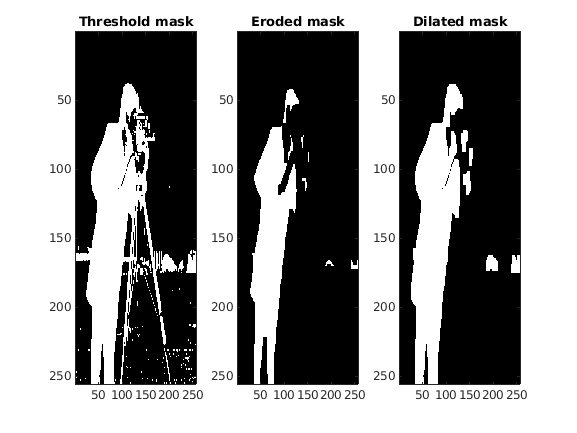

subplot(1,3,1);
imagesc(msk);
title("Threshold mask");
subplot(1,3,2);
imagesc(msk_erode);
title("Eroded mask");
msk_dilate = imdilate(msk_erode,ones(7,7));
subplot(1,3,3);
imagesc(msk_dilate);
title("Dilated mask");

comp = bwconncomp(msk_dilate)

comp = struct with fields:
    Connectivity: 8
       ImageSize: [256 256]
      NumObjects: 6
    PixelIdxList: {[13008×1 double]  [165×1 double]  [214×1 double]  [99×1 double]  [237×1 double]  [218×1 double]}
